parameters= {'CA15','CB15'};


%data_type = {'voltage', 'anode related'};
data_type = {'voltage', 'normal current density'};
%calibration_data_type = {'voltage'};
%calibration_data_type = {'voltage', 'current density', 'Z_ELECTRIC_FIELD'};

metric = 'nmsq';

IPs_IDs1 = 32820:2:32868;

IDs_current_density = [14390, 7400, 4060, 16000, 19860, 23802, 30002, 23822,21212, 8437];

IDs = {py.list(IPs_IDs1), py.list(IDs_current_density)};

IDs_matarr = {IPs_IDs1, IDs_current_density};



%DOE_range1 = [8, 12; 5.5, 8.5]; 
%DOE_range1 = DOE_range1/2880*57.576;
DOE_range1 = [0.15, 0.275; 0.1100,  0.19];

%DOE_range2 = [1.4, 2.5; 2.6, 3.8];
%DOE_range3 = [1.8, 2.8; 2.2, 3.7];
%}
%DOE experiment for 2 varaibles using Central Composite Design
Central_composite_points = ccdesign(2, 'type', 'inscribed', 'center' , 4);

DOE_sample_points15 = reverse_normalization(Central_composite_points, DOE_range1);

%DOE_sample_points = [DOE_sample_points ;reverse_normalization(Central_composite_points, DOE_range2)];
root_folder = 'D:\DOE_nd_data_generation\TIme_step\readyToTimeStepUsingV10_B\year_15';
simulation_seed_folder = fullfile(root_folder, 'Initial_files');
%simulation_seed_folder  = "C:\Users\msapkota\EXPERIMENT\DOE_nd_data_generation\Model_updated_linear\Parameter_BARE_Zone1\Initial_files1";

collection_dir = fullfile(root_folder, 'Simulation_results');

%IDs_types = {'Internal Points', 'MASS_LOSS_RATE'};
IDs_types = {'Internal Points', 'Mesh Points'};

parameters_np_array1 = convert_arr_to_python_2d_list(DOE_sample_points15);


snapshots_py = py.BEASY_IN_OUT2.snapshots_for_given_parameters_and_IDs(py.list(source_parameters), py.list(parameters), parameters_np_array1, py.list(IDs), py.list(response_data_type), simulation_seed_folder, collection_dir, py.list(IDs_types));

snapshots = double(snapshots_py);

surrogates15 = response_surface(DOE_sample_points15, snapshots, 2);
%}

calib_dir = fullfile(root_folder,'Calibration_data');
%meas_dir1 = 'C:\Users\msapkota\EXPERIMENT\DOE_nd_data_generation\Model_updated_nonlinear\Parameter_BARE_BBS\Measurement_results3';

files_name = 'BU_TimeStepped_01_15';
%meas_dict = py.BEASY_IN_OUT1.get_output_data_for_IDs_from_simulation_folder(meas_dir, files_name, py.list(calibration_data_type),  py.list(IDs), py.list(IDs_types));

%meas_data = convert_pydict2data(meas_dict,0);

calib_data_file_err_inc = strcat('data_with_error_',strjoin(data_type, '_'), '.xlsx');

%all_position_dict = py.BEASY_IN_OUT2.get_output_data_for_IDs_from_simulation_folder(calib_dir, files_name, py.list(data_type),  py.list(IDs), py.list(IDs_types));



if ~isfile(fullfile(calib_dir, calib_data_file_err_inc))
    all_position_dict = py.BEASY_IN_OUT2.get_output_data_for_IDs_from_simulation_folder(calib_dir, files_name, py.list(data_type),  py.list(IDs), py.list(IDs_types));
    all_position_data = convert_pydict2data(all_position_dict,0);
    all_position_dict_with_error = introduce_error_and_write_file({IPs_IDs1.', IDs_current_density.'},   all_position_data, calib_dir, calib_data_file_err_inc,3);
end
calib_data_inc_error = data_from_tables(fullfile(calib_dir, calib_data_file_err_inc),IDs_matarr ,3);
%surro_out = output_from_surrogates(calib_breakdown_factor(:,4).', surrogates, [9,6]);

%calib_data_inc_error = data_from_tables(fullfile(meas_dir, meas_data_file_err_inc), {MPs_IDs1, IDs_current_density},3);

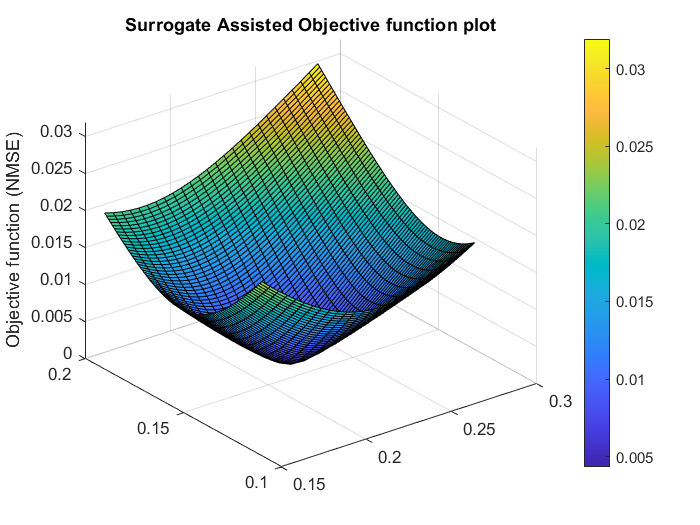

%plot_and_save(meas_dict, meas_data, 'adfa', meas_dir)
figure;

ax = gca;

[plot_data, fmin, min_out_pos1] = plot_objective_with_surrogates(ax, DOE_range1, surrogates15, calib_data_inc_error, 'nmsq', data_type, [length(IDs{1}), length(IDs{2})],[0.7,0.3], [0.005,0.001]);

min_out_pos1

min_out_pos1 =     0.2000    0.1400


%min_out_pos = [0.1999  0.1390];
min_out_pos = [0.1950    0.1440];
%min_out_pos = [9.5600 7.5700]
%repetitive_calibration_count = 2;
solution_folder = '';
for i = 1:length(parameters)
    solution_folder =   strcat(solution_folder, parameters{i},'_', num2str(min_out_pos(i), '%.4f'));
    if i~=length(parameters)
        solution_folder = strcat(solution_folder, '_');
    end
end
solution_colection_dir = fullfile(root_folder,'Solution_results');

solution_dir = fullfile(solution_colection_dir, solution_folder);

if ~isfolder(solution_dir)
    solution_dict = py.BEASY_IN_OUT2.get_response_data_for_IDs_and_input_parameters(py.list(parameters), min_out_pos, simulation_seed_folder, solution_colection_dir,  py.list(data_type), py.list(IDs),  py.list(IDs_types));
    solution_data = convert_pydict2data(solution_dict,1);
else

    solution_dict = py.BEASY_IN_OUT2.get_output_data_for_IDs_from_simulation_folder(solution_dir, files_name, py.list(data_type),  py.list(IDs), py.list(IDs_types));
    solution_data = convert_pydict2data(solution_dict,0);
end

%plotting_response_data(meas_data_inc_error, solution_data)

figure;

ax = gca;

difference_in_bar_chart(ax,solution_data{2}, calib_data_inc_error{2},{'simulation data from calibrated model','calibration data', 'difference'});

set(ax,'XAxisLocation','bottom');

ylabel('mass loss per year')
xlabel('anode IDs')
%}

function output_data = convert_pydict2data2(py_dict_data, extra_cell_provided)

output_data = cell(size(py_dict_data,2)-extra_cell_provided,1);

for i = 1:size(py_dict_data,2)-extra_cell_provided
    output_data{i} = convert_py_list_to_mat_arr(py.model_validation1.get_list_of_values(py_dict_data{i+extra_cell_provided}));
end
end


function de_normaised_data = reverse_normalization(normalised_data, value_ranges)

de_normaised_data = zeros(size(normalised_data));

for i = 1:size(normalised_data, 2)
    
    de_normaised_data(:,i) = value_ranges(i,1)+ diff(value_ranges(i,:))/2 * (normalised_data(:,i)-(-1));
    
end
end